### Leitura dos dados

clear; close all; clc;

file = readtable('dados.xlsx');
idf.t = file.tempo;

idf.u = file.entrada/255; %Valor da entrada: Duty Cicle (0 a 1) 
idf.y = file.saida/340*60/0.01; % Valor da saída: RPM

Ts = 0.01; % 10ms

### Filtragem dos dados

fy = 10; % Janela do filtro de saída
fu = 5; % Janela do filtro de entrada

idf.uf = movmean(idf.u,fu);
idf.yf = movmean(idf.y,fy);

### Offset dos dados

% Definição dos offsets
idf_uo = 0;
idf_yo = idf.yf(1);

% Valores calculados a partir do offset
idf.uo = idf.uf - idf_uo;
idf.yo = idf.yf - idf_yo;

### Plot dos dados

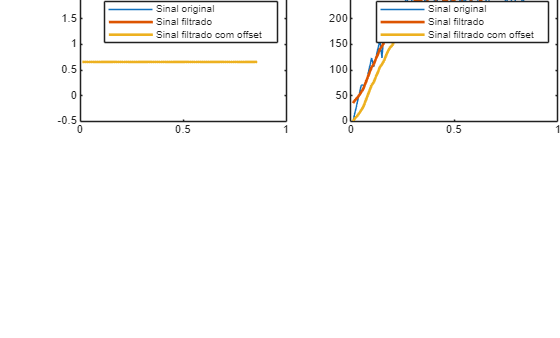

subplot(2,2,1);
plot(idf.t,idf.u);hold on;
plot(idf.t,idf.uf, 'LineWidth',2);
plot(idf.t,idf.uo, 'LineWidth',2);
legend('Sinal original', 'Sinal filtrado', 'Sinal filtrado com offset');
title('Dados da Entrada - Identificação');

subplot(2,2,2);
plot(idf.t,idf.y);hold on;
plot(idf.t,idf.yf, 'LineWidth',2);
plot(idf.t,idf.yo, 'LineWidth',2);
legend('Sinal original', 'Sinal filtrado', 'Sinal filtrado com offset');
title('Dados da Saída - Identificação');

### Parâmetros do modelo

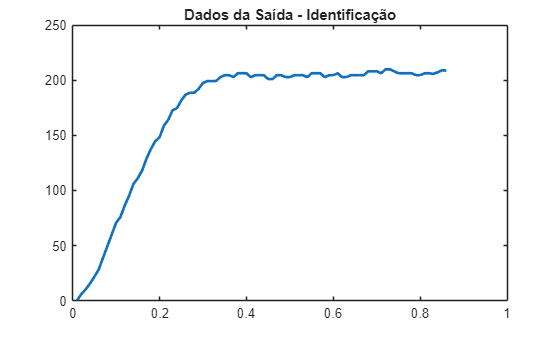

tamanho = length(idf.yo);
amostras = 40;
soma = 0;

for k=tamanho-amostras+1:tamanho
    soma = soma + idf.yo(k);
end

vMax = soma/amostras;

idx = find(idf.yo <= vMax * 0.632, 1, 'last');
tau = idf.t(idx);

figure;
plot(idf.t,idf.yo, 'LineWidth',2);
title('Dados da Saída - Identificação');

k = vMax/idf.u(1);

s = tf('s');
Gs = k/(tau*s + 1) % RPM / Duty Cicle


Gs =
 
    312.5
  ----------
  0.17 s + 1
 
Continuous-time transfer function.


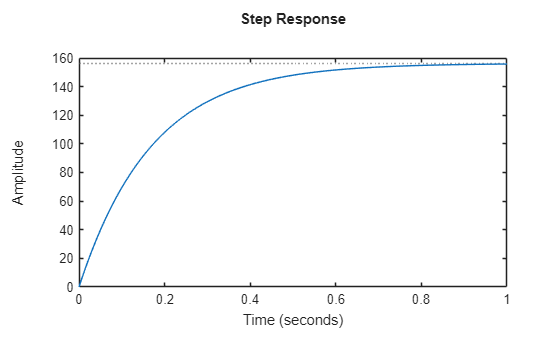

figure;
step(Gs*0.5);

### Discretização

Gz = c2d(Gs,Ts)


Gz =
 
    17.85
  ----------
  z - 0.9429
 
Sample time: 0.01 seconds
Discrete-time transfer function.


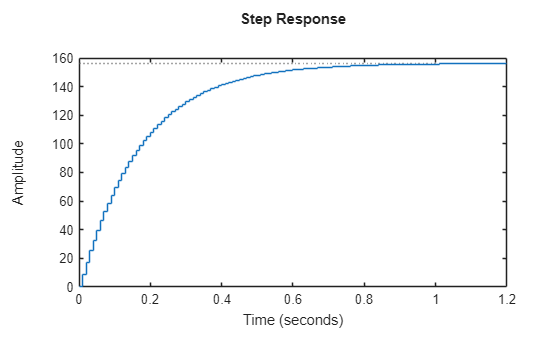

figure;
step(Gz*0.5);

### Otimização

Kp_ini = 0.01;Ki_ini = 0.01;Kd_ini = 0.01;
x0 = [Kp_ini Ki_ini Kd_ini];

% Limites dos Parâmetros

Kp_max = 100; Ki_max = 100; Kd_max = 100;
Kp_min = 0; Ki_min = 0; Kd_min = 0;

v_max = [Kp_max Ki_max Kd_max];
v_min = [Kp_min Ki_min Kd_min];

% Especificação desejada

Tsettle = 0.3;

% Tempo amostragem e simulação

Tsim = 10;
tempo = 0:Ts:Tsim-Ts;
% Degrau unitário

u = ones(length(tempo),1);

% Saída de referência

s = tf('s');
tau = Tsettle/4;

Gref = 1/(tau*s + 1);
yref = lsim(Gref,u,tempo);

% Definição do problema de otimização

options = optimset('Display','iter','MaxFunEvals',500);
[p,fval] = fmincon(@controle.funcao_custo, x0,[],[],[],[], v_min,v_max,[],options,yref,Ts,Tsim,Gz);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    2.677601e+00    0.000e+00    7.235e+01
    1       8    1.843907e+00    0.000e+00    3.468e+00    1.050e-01
    2      12    1.776170e+00    0.000e+00    1.301e+01    2.952e-02
    3      16    1.555057e+00    0.000e+00    5.609e+01    2.084e-02
    4      21    1.331713e+00    0.000e+00    1.238e+02    2.504e-02
    5      26    1.133408e+00    0.000e+00    9.578e+01    9.861e-03
    6      31    1.109179e+00    0.000e+00    8.954e+00    4.599e-04
    7      36    9.502573e-01    0.000e+00    1.208e+02    2.945e-02
    8      41    7.602546e-01    0.000e+00    2.546e+02    3.782e-02
    9      47    7.104860e-01    0.000e+00    1.852e+02    2.053e-02
   10      52    6.707370e-01    0.000e+00    1.200e+03    3.081e-02
   11      56    5.233239e-01    0.000e+00    4.286e+02    2.552e-02
   12      61    4.556492e-01    0.000e+00    6

### Controlador Digital PID

Kp=p(1);Ki=p(2);Kd=p(3);N=0;
Gc = pid(Kp,Ki,Kd,N,Ts,'IFormula','BackwardEuler');

%% Modelos discreto em malha fechada

Gmf1 = feedback(Gz,1);
Gmf2 = feedback(Gz*Gc,1);

%step(Gmf1,1);
step(Gmf2,1);
stepinfo(Gmf2)

ans = struct with fields:
         RiseTime: 0.1700
    TransientTime: 0.3000
     SettlingTime: 0.3000
      SettlingMin: 0.9093
      SettlingMax: 1.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0000
         PeakTime: 0.8900


### Controlador - Equação de Diferenças

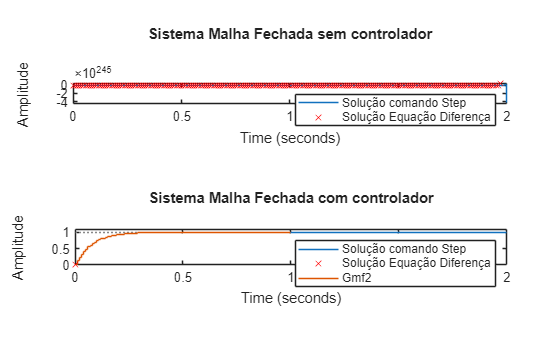

time = 2/Ts; % Tempo de simulação
r = ones(1,time)*150; % Degrau unitário

y1 = step(Gmf1,1);
y2 = step(Gmf2,1);

for k = 1:time
    switch k
        case 1
            y1(k) = 0; % Saída da planta em Malha Fechada sem Controlador
            y2(k) = 0; % Saída da planta em Malha Fechada com Controlador
            e(k) = r(k)-y2(k); % Erro
            u(k) = (Kp + Ki * Ts + Kd/Ts)*e(k); % Sinal de saída do controlador
        case 2
            y1(k) = 17.85 * r(k-1) - 16.91 * y1(k-1);
            y2(k) = 0.9429*y2(k-1) + 17.85*u(k-1);
            e(k) = r(k)-y2(k);
            u(k) = u(k-1) + Kp*e(k) - Kp*e(k-1) + Ki*Ts*e(k) + (Kd/Ts) * (e(k) - 2*e(k-1));
        otherwise
            y1(k) = 17.85 * r(k-1) - 16.91 * y1(k-1);
            y2(k) = 0.9429*y2(k-1) + 17.85*u(k-1);
            e(k) = r(k)-y2(k);
            u(k) = u(k-1) + Kp*e(k) - Kp*e(k-1) + Ki*Ts*e(k) + (Kd/Ts) * (e(k) - 2*e(k-1) + e(k-2));
    end
end

%% Plot dos gráficos
subplot(2,1,1);

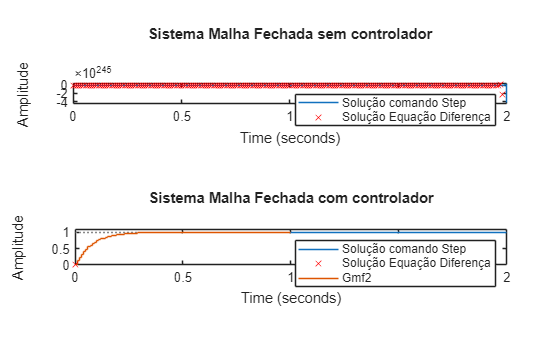

step(Gmf1,2); hold on; stairs([0:(time-1)]*Ts,y1,'rx');
title("Sistema Malha Fechada sem controlador");
legend('Solução comando Step', 'Solução Equação Diferença');

subplot(2,1,2);

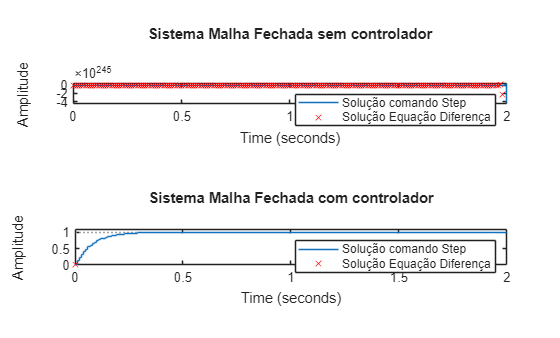

step(Gmf2,2); hold on; stairs([0:(time-1)]*Ts,y2,'rx');
title("Sistema Malha Fechada com controlador");
legend('Solução comando Step', 'Solução Equação Diferença');